i2 = imread('peppers.png');

ans =    384   512     3


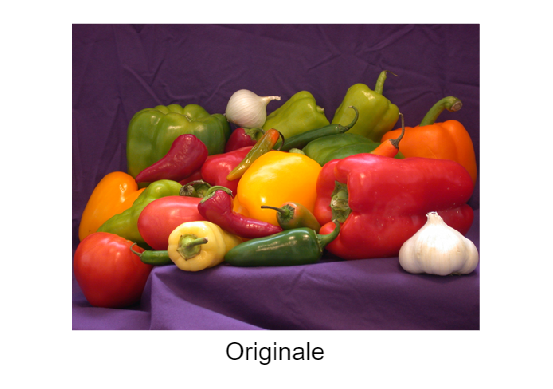

imshow(i2)
text(size(i2,2)/2, size(i2,1) + 10, 'Originale', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Applicazione Rumore Rayleigh

img = im2double(i2);
sigma = 0.1525; % Parametro di Scala (spread)
% Valore di scala per avere varianza ≈ 0.01

rayleigh_noise = raylrnd(sigma, size(img));
noise_zero_mean = rayleigh_noise - (sqrt(pi/2) * sigma);
noisy_img = img + noise_zero_mean;
noisy_img = min(max(noisy_img, 0), 1);

Mostra Immagine

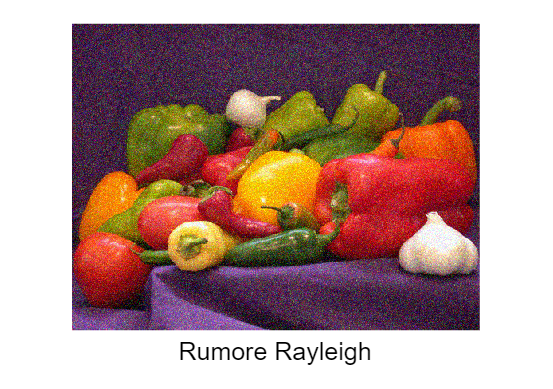

imshow(noisy_img)
img_noisy = noisy_img;
text(size(i2,2)/2, size(i2,1) + 10, 'Rumore Rayleigh', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Filtro Weiner

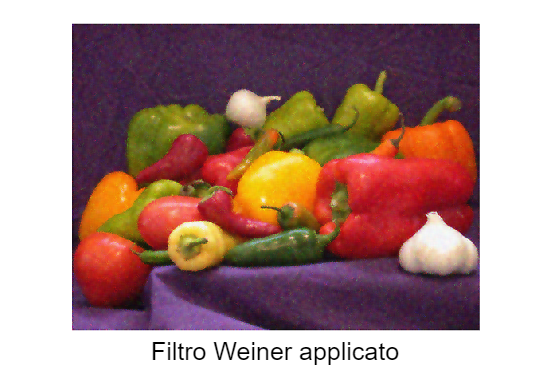

img_denoisedw = img_noisy;
for c = 1:3
    img_denoisedw(:,:,c) = wiener2(noisy_img(:,:,c), [5 5]);
end

imshow(img_denoisedw,[])
text(size(i2,2)/2, size(i2,1) + 10, 'Filtro Weiner applicato', ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'top', 'FontSize', 12);

Confronto PNSR tanto per

% Conversione per confronto corretto
I_originale = im2double(i2);

% PSNR tra originale e immagine rumorosa
[peaksnr1, snr1] = psnr(noisy_img, I_originale)

peaksnr1 = 20.3406

snr1 = 12.3646


[peaksnr3, snr3] = psnr(img_denoisedw, I_originale)

peaksnr3 = 29.2026

snr3 = 21.2266